# BDX Droid Long Jump

Run bdx droid (Serial chain - joints are connected in sequence)

arc-bridge branch name = altmands

droid index = 0 (droid)

First run arc-bridge with the option --block to wait for control command

Run this matlab script

remember to generate the lcm messages: rabbit_state_t & rabbit_control_t

Direct Collocation is done in matlab and sent to arc-bridge for visualization

% Setup LCM protocol
lcm_cmd_topic = "bdx_droid_control";
lcm_state_topic = "bdx_droid_state";
lc = lcm.lcm.LCM.getSingleton();
getenv("LCM_DEFAULT_URL")


ans =

  0×0 empty char array




aggregator = lcm.lcm.MessageAggregator();
aggregator.setMaxMessages(1);
lc.subscribe(lcm_state_topic, aggregator);

control_freq = 500; % control frequency in Hz
rate_ctrl = rateControl(control_freq);
dt_ctrl = 1 / control_freq;
steps = 1000;

% Parameters
p.g = 9.81;
p.l = [0.2, 0.4, 0.4]';
p.M = [10 1 0.5]';
p.I = [0.01 0.005 0.005]';
p.params = [p.g; p.l; p.M; p.I];
p.mu = 1;
p.alpha = 0.5;

% SLIP parameters
p.l0 = 0.6;  % Rest length
p.k = 6000;  % Stiffness
p.c = 250;   % Damping
p.M_eff = sum(p.M);

% Initial state - MUST MATCH optimization X0
rs.qb = [0.0; 0.6];  
rs.dqb = [1.5; 0.0];  % Start with horizontal velocity
rs.pf = [-0.04, 0.0; 0.04, 0.0];

import casadi.*

% Optimization params
p.N = 60;
ds = 1/p.N;
Umax_val = 5000;

% Initial condition: [x; z; dx; dz]
% Start with horizontal velocity for long jump
X0 = [0.0; p.l0; 1.5; 0.0];

opti = casadi.Opti();
X = opti.variable(4,p.N+1);
U = opti.variable(2,p.N+1);
tf = opti.variable(1,1);
dt_optm = tf * ds;

obj = MX(0);
opti.subject_to(X(:,1) == X0);

% Terminal constraints - long jump landing
opti.subject_to(X(1,end) >= 0.8);  % Jump at least 0.8m horizontally
opti.subject_to(X(2,end) >= p.l0 * 0.85);  % Land near rest height
opti.subject_to(X(2,end) <= p.l0 * 1.05);
opti.subject_to(-0.5 <= X(4,end));  % Allow some downward velocity
opti.subject_to(X(4,end) <= 0.2);
opti.subject_to(X(3,end) >= 0);  % Keep moving forward at landing

opti.subject_to(0.4 <= tf);
opti.subject_to(tf <= 1.2);

% Define stance phase (first 40% of motion)
stance_fraction = 0.35;
N_stance = floor(stance_fraction * p.N);

% Collocation loop
for kk = 1:p.N
    Xk = X(:,kk);
    Uk = U(:,kk);
    Xkp1 = X(:,kk+1);
    Ukp1 = U(:,kk+1);

    % Stance phase indicator
    in_stance = (kk <= N_stance);
    
    % Objective
    if in_stance
        % During stance: apply strong forward push
        obj = obj + 0.005 * Uk'*Uk;
        obj = obj + 0.002 * (Ukp1-Uk)'*(Ukp1-Uk);
    else
        % During flight: minimize forces
        obj = obj + 0.05 * Uk'*Uk;
    end
   
    % Dynamics
    fk = dynamics_SLIP(Xk,Uk,p);
    fkp1 = dynamics_SLIP(Xkp1,Ukp1,p);
    opti.subject_to(Xkp1 == Xk + 0.5*dt_optm*(fk + fkp1));

    % Path constraints
    opti.subject_to(Xk(2) >= 0.05);  % Above ground
    
    if in_stance
        % Stance phase: high vertical force, some horizontal
        opti.subject_to(Uk(2) >= 0);
        opti.subject_to(Uk(1)^2 + Uk(2)^2 <= Umax_val^2);
        opti.subject_to(-1500 <= Uk(1));  % Allow backward push
        opti.subject_to(Uk(1) <= 1500);   % Allow forward push
    else
        % Flight phase: no ground forces
        opti.subject_to(Uk(1) == 0);
        opti.subject_to(Uk(2) == 0);
    end

end

% Terminal cost - maximize distance, soft landing
obj = obj + 5 * tf^2;  % Minimize time
obj = obj - 200 * X(1,end);  % Maximize horizontal distance
obj = obj + 50 * X(3,end)^2;  % Penalize high forward velocity at landing
obj = obj + 200 * (X(4,end))^2;  % Soft vertical landing

opti.minimize(obj);

opti.set_initial(tf, 0.7);
opti.set_initial(X, repmat(X0, 1, p.N+1));
opti.set_initial(U, 0);
opti.solver('ipopt');
sol = opti.solve();

This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:     1282
Number of nonzeros in inequality constraint Jacobian.:      173
Number of nonzeros in Lagrangian Hessian.............:      409

Total number of variables............................:      367
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      322
Total number of inequality constraints...............:      152
        inequality constraints with only lower bounds:      107
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:       45

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  1.1495000e+02 8.00e-01 5.16e-01  -1.0 0.00e+00    -  0.00e+00 0.00e+00 


Xout = sol.value(X);
Uout = sol.value(U);
tf_val = sol.value(tf);
tout = linspace(0,tf_val,p.N+1);

fprintf('=== Optimization Results ===\n');

=== Optimization Results ===


fprintf('Initial: x=%.3f, z=%.3f, dx=%.3f, dz=%.3f\n', ...
    Xout(1,1), Xout(2,1), Xout(3,1), Xout(4,1));

Initial: x=0.000, z=0.600, dx=1.500, dz=0.000


fprintf('Final:   x=%.3f, z=%.3f, dx=%.3f, dz=%.3f\n', ...
    Xout(1,end), Xout(2,end), Xout(3,end), Xout(4,end));

Final:   x=0.800, z=0.510, dx=0.055, dz=0.073


fprintf('Jump time: %.3f s, distance: %.3f m\n', tf_val, Xout(1,end));

Jump time: 0.434 s, distance: 0.800 m


fprintf('Max height: %.3f m (gain: %.3f m)\n', ...
    max(Xout(2,:)), max(Xout(2,:))-Xout(2,1));

Max height: 0.704 m (gain: 0.104 m)


fprintf('Max force: %.1f N\n', max(sqrt(Uout(1,:).^2 + Uout(2,:).^2)));

Max force: 8865.4 N


fprintf('Jump angle: %.1f deg\n', ...
    atand((Xout(2,N_stance)-Xout(2,1))/(Xout(1,N_stance)-Xout(1,1))));

Jump angle: 15.3 deg


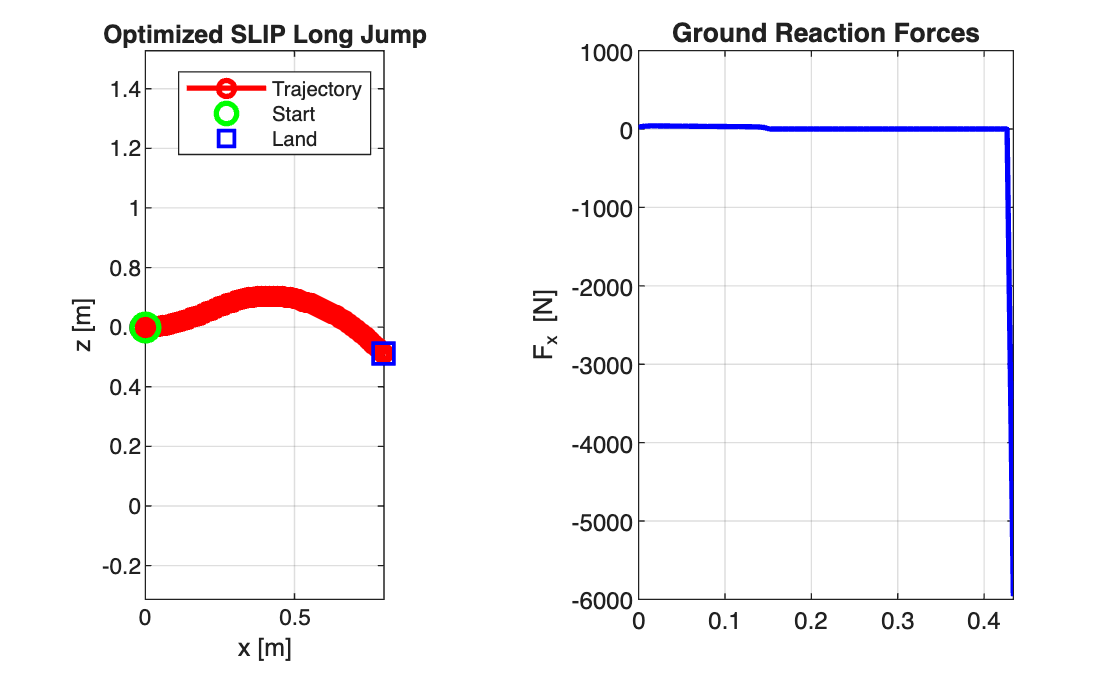


% Plot trajectory
figure;
subplot(1,3,1);
plot(Xout(1,:), Xout(2,:), 'r-o', 'LineWidth', 2); hold on;
plot(Xout(1,1), Xout(2,1), 'go', 'MarkerSize', 10, 'LineWidth', 2);
plot(Xout(1,end), Xout(2,end), 'bs', 'MarkerSize', 10, 'LineWidth', 2);
xlabel('x [m]'); ylabel('z [m]');
title('Optimized SLIP Long Jump');
legend('Trajectory', 'Start', 'Land');
grid on; axis equal;

subplot(1,2,2);
plot(tout, Uout(1,:), 'b-', 'LineWidth', 2);
ylabel('F_x [N]');
title('Ground Reaction Forces');
grid on;

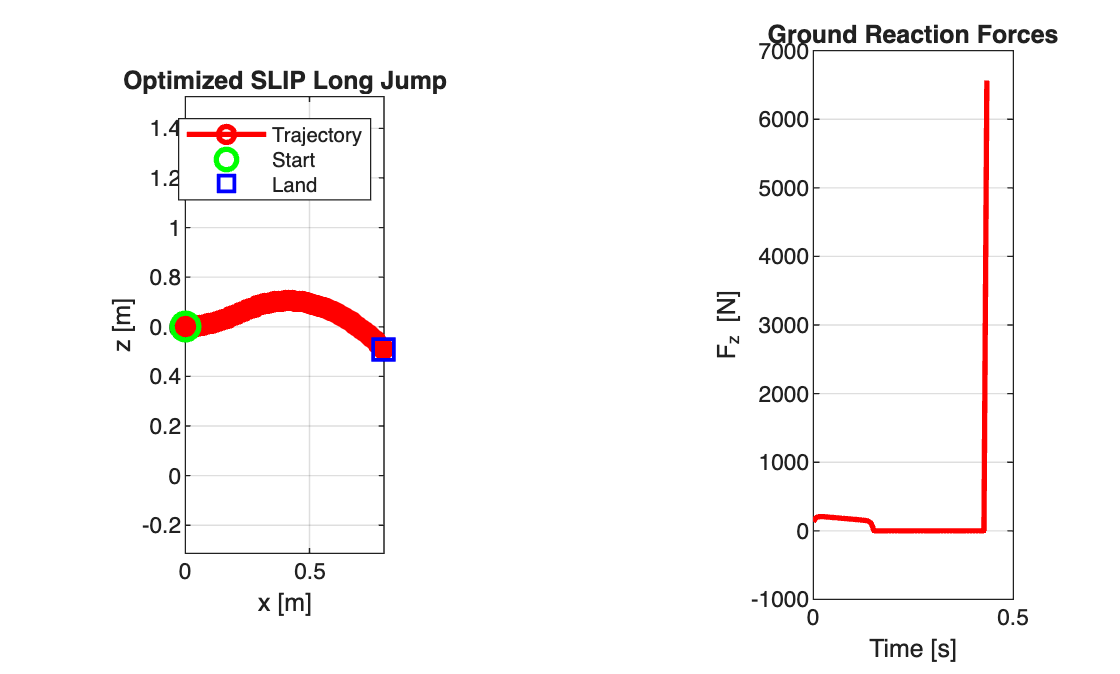


subplot(1,3,3);
plot(tout, Uout(2,:), 'r-', 'LineWidth', 2);
ylabel('F_z [N]');
xlabel('Time [s]');
title('Ground Reaction Forces');
grid on;


%% Real-Time Control Loop

fprintf("\n=== Starting LCM Control Loop ===\n")


=== Starting LCM Control Loop ===



rs2DSLIP = [];
state_history = zeros(steps, 18);
actual_history = zeros(steps, 4);
command_history = zeros(steps, 10);

for k = 1:steps
    
    msg = aggregator.getNextMessage(0);
    t = (k - 1) * dt_ctrl;
    
    if isempty(msg)
        rate_ctrl.waitfor();
        continue
    end
    
    lc_state = eval("lcm_msgs."+lcm_state_topic+"_t(msg.data)");
    lc_cmd = eval("lcm_msgs."+lcm_cmd_topic+"_t()");

    % Update robot state from LCM
    rs.qb = [lc_state.position(1); lc_state.position(3)];
    rs.dqb = [lc_state.velocity(1); lc_state.velocity(3)];
    rs.pitch = lc_state.rpy(2);  % Body pitch angle
    rs.qj = lc_state.qj_pos(1:10);
    rs.dqj = lc_state.qj_vel(1:10);
    rs.pf = [lc_state.p_gc(1), lc_state.p_gc(3);
             lc_state.p_gc(4), lc_state.p_gc(6)];

    % Initialize SLIP state on first iteration
    if isempty(rs2DSLIP)
        rs2DSLIP = init2DSLIPState(rs, p);
        fprintf('Initial state: x=%.3f, z=%.3f, dx=%.3f, dz=%.3f\n', ...
            rs.qb(1), rs.qb(2), rs.dqb(1), rs.dqb(2));
    end

    % Update SLIP leg dynamics
    [rs2DSLIP, F_legs] = update2DSLIPState(rs2DSLIP, rs, p, dt_ctrl, t);
    
    % Get reference trajectory
    if t <= tf_val
        [~, plan_idx] = min(abs(tout - t));
        plan_idx = min(plan_idx, p.N+1);
    else
        plan_idx = p.N + 1;
    end
    
    Xref = Xout(:, plan_idx);
    Uref = Uout(:, plan_idx);
    
    % Determine if in stance or flight phase
    in_stance = (plan_idx <= N_stance);

    % Foot placement strategy
    if in_stance
        % Stance: keep feet planted at touchdown positions
        pf_des = [rs2DSLIP.legs(1).footPos_touchdown';
                  rs2DSLIP.legs(2).footPos_touchdown'];
    else
        % Flight: sweep feet forward for landing
        % Predict landing position based on current trajectory
        time_to_land = max(0.1, tf_val - t);
        
        % Use current velocity for better prediction
        x_land_predict = rs.qb(1) + rs.dqb(1) * time_to_land * 0.7;  % Conservative estimate
        
        % Place feet ahead and slightly wider for stability
        foot_separation = 0.10;  % 10cm apart laterally
        foot_forward_offset = 0.05;  % 5cm ahead of predicted COM landing
        
        pf_des = [x_land_predict + foot_forward_offset - foot_separation, 0.0;
                  x_land_predict + foot_forward_offset + foot_separation, 0.0];
    
    end

    % Desired pitch angle (keep torso upright or slightly leaning back)
    if in_stance
        pitch_des = -0.1;  % Slight backward lean during stance for forward push
    else
        pitch_des = 0.05;  % Slight forward lean during flight for landing preparation
    end
    
    % Compute desired joint angles with pitch control
    q_des_10dof = SLIP_to_joints(Xref(1:2), pf_des, p, pitch_des);
    
    % Adaptive PD gains based on phase
    if in_stance
        % High gains during stance for force generation
        Kp_scale = [2.0, 2.0, 3.0, 3.0, 1.0, 2.0, 2.0, 3.0, 3.0, 1.0];
        Kd_scale = [1.5, 1.5, 2.0, 2.0, 1.0, 1.5, 1.5, 2.0, 2.0, 1.0];
    else
        % Higher gains during flight for pitch stabilization
        Kp_scale = [1.5, 1.5, 2.5, 2.5, 0.8, 1.5, 1.5, 2.5, 2.5, 0.8];
        Kd_scale = [1.2, 1.2, 2.0, 2.0, 0.8, 1.2, 1.2, 2.0, 2.0, 0.8];
    end
    
    Kp_full = diag(200 * Kp_scale);
    Kd_full = diag(20 * Kd_scale);

    % Compute torques with pitch stabilization feedback
    tau_fb = Kp_full * (q_des_10dof - rs.qj) - Kd_full * rs.dqj;
    
    % Add explicit pitch stabilization torque during flight
    if ~in_stance
        pitch_error = pitch_des - rs.pitch;
        dpitch = lc_state.omega(2);  % pitch rate
        
        % Pitch stabilization gains (higher during flight)
        Kp_pitch = 80;   % Proportional gain for pitch
        Kd_pitch = 15;   % Derivative gain for pitch
        
        pitch_torque = Kp_pitch * pitch_error - Kd_pitch * dpitch;
        
        % Distribute pitch correction torque to hip joints (opposite legs for balance)
        % Left hip gets positive, right hip gets negative (or vice versa)
        tau_fb(3) = tau_fb(3) + pitch_torque;   % Left hip pitch
        tau_fb(8) = tau_fb(8) + pitch_torque;   % Right hip pitch
    end
    
    % Add feedforward from SLIP forces during stance
    if in_stance
        tau_ff = compute_feedforward_torque(F_legs, rs, p, 0.15);
    else
        tau_ff = zeros(10,1);
    end
    
    tau_full = tau_fb + tau_ff;
    
    % Torque limits
    tau_max = 50;  % Nm per joint
    tau_full = max(-tau_max, min(tau_max, tau_full));

    % Publish commands
    lc_cmd.qj_tau = tau_full;
    lc_cmd.se_pos = [Xref(1); 0; Xref(2)];
    lc_cmd.se_vel = [Xref(3); 0; Xref(4)];
    lc.publish(lcm_cmd_topic, lc_cmd);

    % Log state
    state_history(k,:) = [
        rs2DSLIP.x, rs2DSLIP.z, rs2DSLIP.dx, rs2DSLIP.dz, ...
        rs2DSLIP.legs(1).length, rs2DSLIP.legs(1).angle, ...
        rs2DSLIP.legs(1).dlength, double(rs2DSLIP.legs(1).inStance), ...
        rs2DSLIP.legs(2).length, rs2DSLIP.legs(2).angle, ...
        rs2DSLIP.legs(2).dlength, double(rs2DSLIP.legs(2).inStance), ...
        F_legs', rs.pitch, double(in_stance)];
    
    actual_history(k,:) = [rs.qb; rs.dqb];
    command_history(k,:) = tau_full;

    rate_ctrl.waitfor();

    % Termination conditions
    if t >= tf_val + 0.3
        if abs(rs.qb(2) - p.l0) < 0.15 && abs(rs.dqb(2)) < 0.3
            fprintf('Jump complete at t=%.3f s\n', t);
            fprintf('Final position: x=%.3f, z=%.3f\n', rs.qb(1), rs.qb(2));
            fprintf('Actual distance: %.3f m\n', rs.qb(1));
            
        end
    end

    if t > 2.5
        fprintf('Timeout at t=%.3f s\n', t);
        fprintf('Final position: x=%.3f, z=%.3f\n', rs.qb(1), rs.qb(2));
   
    end
   
end

Initial state: x=-0.087, z=0.242, dx=0.000, dz=0.000



state_history = state_history(1:k,:);
actual_history = actual_history(1:k,:);
command_history = command_history(1:k,:);
t_vec = (0:k-1) * dt_ctrl;

fprintf("=== LCM Control Loop Finished ===\n")

=== LCM Control Loop Finished ===




%% Helper Functions

function q_joints = SLIP_to_joints(com_pos, foot_pos, p, pitch_des)
    x_com = com_pos(1);
    z_com = com_pos(2);
    
    % Use desired pitch directly (not compensating for current pitch)
    ptor = [x_com; z_com; pitch_des];
    
    % Right leg (indices 1,:)
    qR = my_IK(ptor, foot_pos(1,:)', p);
    
    % Left leg (indices 2,:)
    qL = my_IK(ptor, foot_pos(2,:)', p);
    
    q_joints = [qL; qR];
end

function qj = my_IK(ptor, pf, p)
    pc = ptor(1:2);
    th = ptor(3);
    
    l2 = p.l(2);
    l3 = p.l(3);
    r = pf - pc;
    
    % Check reachability
    leg_length = norm(r);
    if leg_length > (l2 + l3) * 0.99
        % Leg too extended - stretch to max
        r = r * (l2 + l3) * 0.99 / leg_length;
    end
    
    % Knee angle
    cos_alpha = (l2^2 + l3^2 - r'*r) / (2*l2*l3);
    cos_alpha = max(-0.99, min(0.99, cos_alpha));
    alpha = acos(cos_alpha);
    qknee = pi - alpha;
    
    % Hip pitch
    beta = atan2(r(1), -r(2));
    cos_gamma = (r'*r + l2^2 - l3^2) / (2*norm(r,2)*l2);
    cos_gamma = max(-1, min(1, cos_gamma));
    gamma = acos(cos_gamma);
    qhip_pitch = -(th + beta + gamma);
    
    % Default joint values
    q_yaw = 0.0;
    qhip_roll = 0.0;
    q_ankle = 0.0;
    
    qj = [q_yaw; qhip_roll; qhip_pitch; qknee; q_ankle];
end

function dX = dynamics_SLIP(X, U, p)
    Fx = U(1);
    Fz = U(2);
    
    ddx = Fx / p.M_eff;
    ddz = (Fz / p.M_eff) - p.g;
    
    dX = [X(3); X(4); ddx; ddz];
end

function rs2DSLIP = init2DSLIPState(rs, p)
    rs2DSLIP.x = rs.qb(1);
    rs2DSLIP.z = rs.qb(2);
    rs2DSLIP.dx = rs.dqb(1);
    rs2DSLIP.dz = rs.dqb(2);
    
    for i = 1:2
        dx = rs2DSLIP.x - rs.pf(i,1);
        dz = rs2DSLIP.z - rs.pf(i,2);
        
        rs2DSLIP.legs(i).length = sqrt(dx^2 + dz^2);
        rs2DSLIP.legs(i).angle = atan2(dz, dx);
        rs2DSLIP.legs(i).dlength = 0;
        rs2DSLIP.legs(i).prevLength = rs2DSLIP.legs(i).length;
        rs2DSLIP.legs(i).footPos = rs.pf(i,:)';
        rs2DSLIP.legs(i).footPos_touchdown = rs.pf(i,:)';
        rs2DSLIP.legs(i).inStance = true;
        rs2DSLIP.legs(i).touchdown_angle = rs2DSLIP.legs(i).angle;
    end
    
    rs2DSLIP.g = p.g;
    rs2DSLIP.M = p.M_eff;
end

function [rs2DSLIP, F_legs] = update2DSLIPState(rs2DSLIP, rs, p, dt, t)
    % Update COM from actual robot
    rs2DSLIP.x = rs.qb(1);
    rs2DSLIP.z = rs.qb(2);
    rs2DSLIP.dx = rs.dqb(1);
    rs2DSLIP.dz = rs.dqb(2);
    
    F_legs = zeros(4,1);
    
    for i = 1:2
        % Current foot position from robot
        foot_pos = rs.pf(i,:)';
        
        % Leg geometry
        dx_leg = rs2DSLIP.x - foot_pos(1);
        dz_leg = rs2DSLIP.z - foot_pos(2);
        
        new_length = sqrt(dx_leg^2 + dz_leg^2);
        new_angle = atan2(dz_leg, dx_leg);
        
        rs2DSLIP.legs(i).dlength = (new_length - rs2DSLIP.legs(i).prevLength) / dt;
        rs2DSLIP.legs(i).length = new_length;
        rs2DSLIP.legs(i).angle = new_angle;
        rs2DSLIP.legs(i).prevLength = new_length;
        rs2DSLIP.legs(i).footPos = foot_pos;
        
        % State transitions
        % Flight -> Stance
        if (~rs2DSLIP.legs(i).inStance) && ...
           (new_length <= p.l0 * 1.05) && ...
           (dz_leg < p.l0 * 0.5) && ...
           (rs2DSLIP.dz < 0)
            
            rs2DSLIP.legs(i).inStance = true;
            rs2DSLIP.legs(i).footPos_touchdown = foot_pos;
            rs2DSLIP.legs(i).touchdown_angle = new_angle;
        end
        
        % Compute leg forces
        Fx_leg = 0;
        Fz_leg = 0;
        
        if rs2DSLIP.legs(i).inStance
            % Spring-damper force along leg axis
            F_spring = p.k * (p.l0 - new_length);
            F_damp = -p.c * rs2DSLIP.legs(i).dlength;
            F_leg_mag = max(0, F_spring + F_damp);
            
            if F_leg_mag > 10  % Threshold to avoid noise
                Fx_leg = F_leg_mag * cos(new_angle);
                Fz_leg = F_leg_mag * sin(new_angle);
            end
            
            % Stance -> Flight (leg extends past rest length)
            if (new_length >= p.l0 * 0.98) && (rs2DSLIP.legs(i).dlength > 0)
                rs2DSLIP.legs(i).inStance = false;
            end
        end
        
        % Store forces [Right leg: 1-2, Left leg: 3-4]
        F_legs((i-1)*2 + 1) = Fx_leg;
        F_legs((i-1)*2 + 2) = Fz_leg;
    end
end

function tau_ff = compute_feedforward_torque(F_legs, rs, p, scale)
    % Map leg forces to joint torques via simplified Jacobian
    tau_ff = zeros(10,1);
    
    % Left leg (joints 1-5): forces in F_legs(3:4)
    Fx_L = F_legs(3);
    Fz_L = F_legs(4);
    
    % Right leg (joints 6-10): forces in F_legs(1:2)
    Fx_R = F_legs(1);
    Fz_R = F_legs(2);
    
    % Simplified torque mapping (moment arm * force)
    % Hip pitch and knee are main contributors
    
    % Left leg
    tau_ff(3) = scale * (Fx_L * p.l(2) * 0.5 + Fz_L * p.l(2) * 0.8);  % Hip pitch
    tau_ff(4) = scale * (Fx_L * p.l(3) * 0.3 + Fz_L * p.l(3) * 0.6);  % Knee
    
    % Right leg
    tau_ff(8) = scale * (Fx_R * p.l(2) * 0.5 + Fz_R * p.l(2) * 0.8);  % Hip pitch
    tau_ff(9) = scale * (Fx_R * p.l(3) * 0.3 + Fz_R * p.l(3) * 0.6);  % Knee
end